# DC-8 PLANE


M = 0.84;
a = 982;
S = 2600;
q = 270;
Cm = -2.017

Cm = -2.0170

Xu = -0.014;
Xw = 0.0043;
g = 32.086614;
theta0 = 0;
Zu = -0.0735;
Zw = -0.806;
u0 = M*a

u0 = 824.8800

Mu = -0.000786;
Mw = -0.011;
Mwdot = -0.00051;
Mq = -0.924;

## The General Set of Equations


A = [Xu Xw 0 -g*cos(theta0);
    Zu Zw u0 -g*sin(theta0);
    (Mu+Mwdot*Zu) (Mw+Mwdot*Zw) (Mq+u0*Mwdot) (-Mwdot*g*sin(theta0))
    0 0 1 0]

A =    -0.0140    0.0043         0  -32.0866
   -0.0735   -0.8060  824.8800         0
   -0.0007   -0.0106   -1.3447         0
         0         0    1.0000         0


[eigs] = eig(A)

eigs =   -1.0765 + 2.9435i
  -1.0765 - 2.9435i
  -0.0059 + 0.0232i
  -0.0059 - 0.0232i


Zeta_sp = sqrt(1/(1+(imag(eigs(1))/(real(eigs(1))))^2))

Zeta_sp = 0.3435

Wn_sp = -real(eigs(1))/Zeta_sp

Wn_sp = 3.1342

Zeta_ph = sqrt(1/(1+(imag(eigs(3))/(real(eigs(3))))^2))

Zeta_ph = 0.2455

Wn_ph = -real(eigs(3))/Zeta_ph

Wn_ph = 0.0239

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G_sp = Wn_sp^2/(s^2+2*Wn_sp*Zeta_sp*s+Wn_sp^2)

G_sp =
 
          9.823
  ---------------------
  s^2 + 2.153 s + 9.823
 
Continuous-time transfer function.





G_ph = (Wn_ph^2)/(s^2+2*Zeta_ph*Wn_ph*s+Wn_ph^2)

G_ph =
 
           0.0005716
  ---------------------------
  s^2 + 0.01174 s + 0.0005716
 
Continuous-time transfer function.



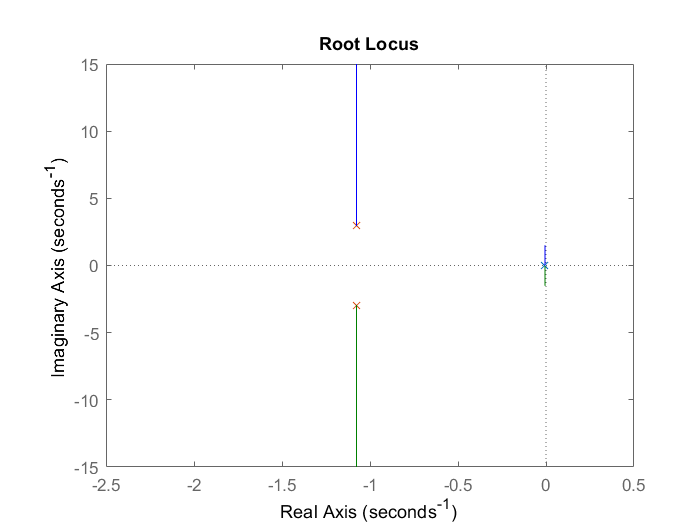


rlocus(G_ph)
hold on
rlocus(G_sp)
hold off

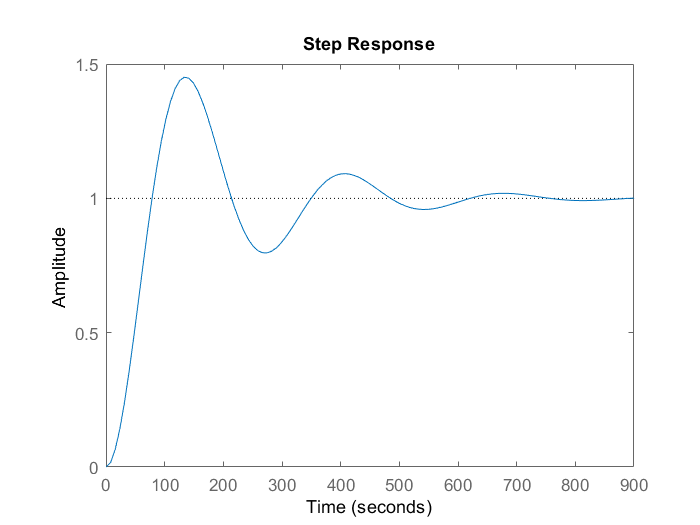

step(G_ph)

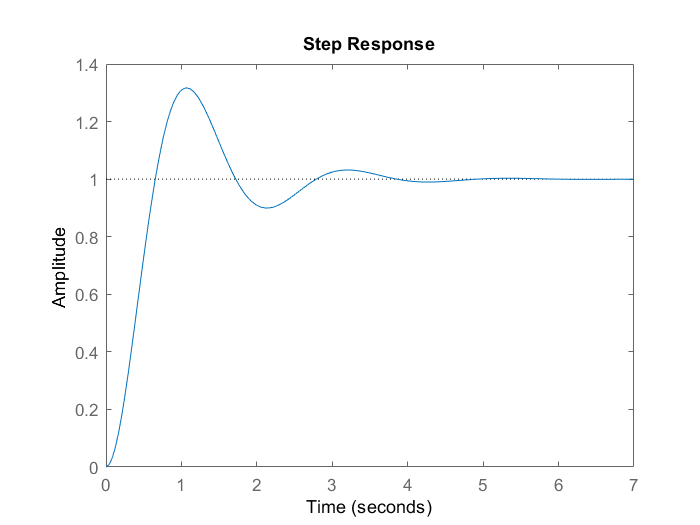

step(G_sp)

## Short Period Approximations

 A_short = [Zw u0;
   (Mw+Mwdot*Zw) (Mq+Mwdot*u0)];
wn_sp_appr = sqrt(Zw*Mq-u0*Mw)

wn_sp_appr = 3.1334

zet_sp_appr = -(Zw+Mq+u0*Mwdot)/(2*wn_sp_appr)

zet_sp_appr = 0.3432

G_sp_apprx = (wn_sp_appr^2)/(s^2+2*wn_sp_appr*zet_sp_appr*s+wn_sp_appr^2)

G_sp_apprx =
 
          9.818
  ---------------------
  s^2 + 2.151 s + 9.818
 
Continuous-time transfer function.



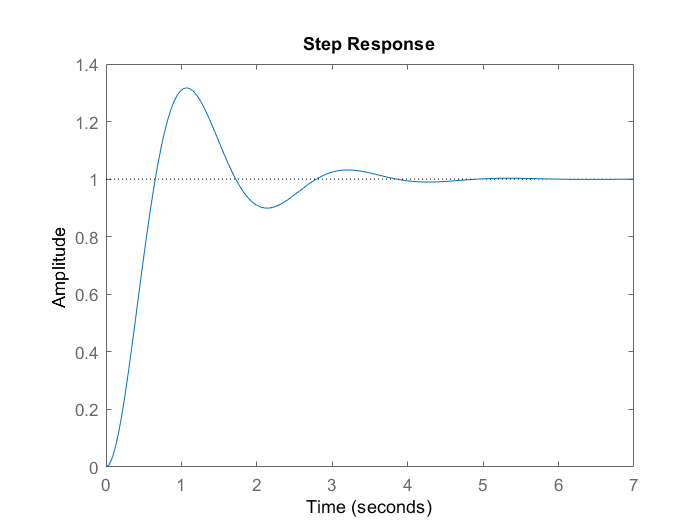

step(G_sp_apprx)

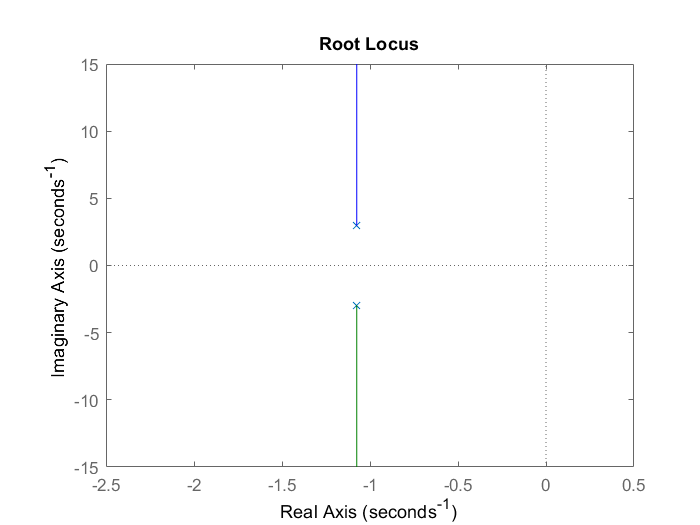

rlocus(G_sp_apprx)

## Phugoid Mode Approximations

A_ph = [Xu -g;
    -Zu/u0 0];
Wn_ph_appr = sqrt((-g/u0)*Zu)

Wn_ph_appr = 0.0535

Zeta_ph_appr = -(Xu/(2*Wn_ph_appr))

Zeta_ph_appr = 0.1309

G_ph_appr = (Wn_ph_appr^2)/(s^2+2*Zeta_ph_appr*...
    Wn_ph_appr*s+Wn_ph_appr^2)

G_ph_appr =
 
          0.002859
  ------------------------
  s^2 + 0.014 s + 0.002859
 
Continuous-time transfer function.



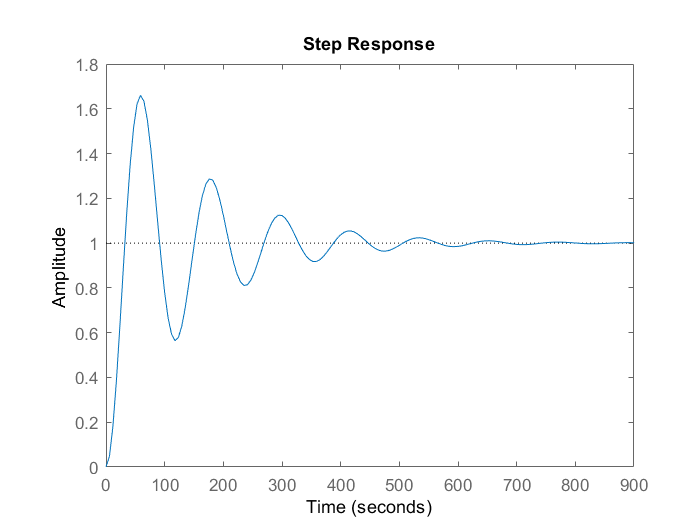

step(G_ph_appr)

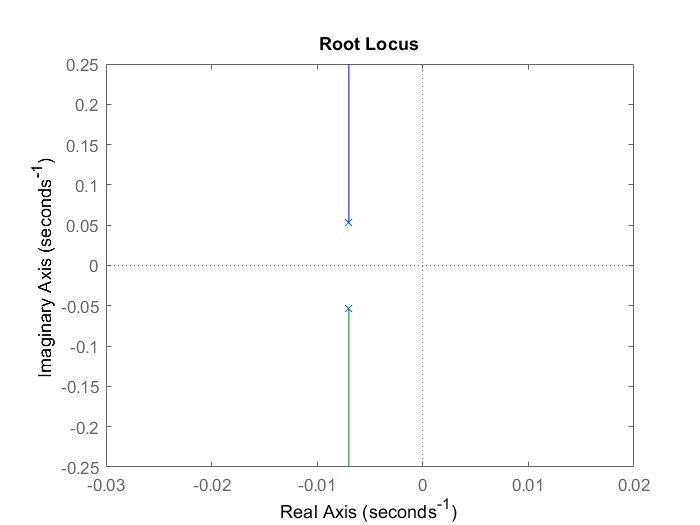

rlocus(G_ph_appr)